# Q1

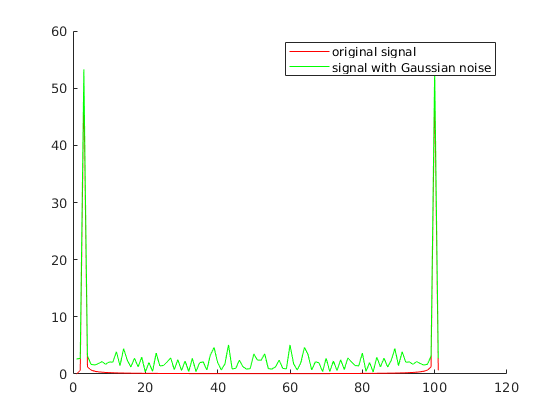

rng default
x = 0:pi/50:2*pi;
f = sin(2*x);
y = f + randn(size(x))*0.2;
f1 = smooth(y)';
Ff = fft(f);
Fy = fft(y);
figure(1)
hold on
plot(abs(Ff),'r');plot(abs(Fy),'g');
legend('original signal','signal with Gaussian noise')
hold off

可见原始信号和含噪声信号的两端峰值基本重合。但是原始信号的中间部分较为光滑且为0，含噪声信号的中间部分不光滑，但基本小于5。

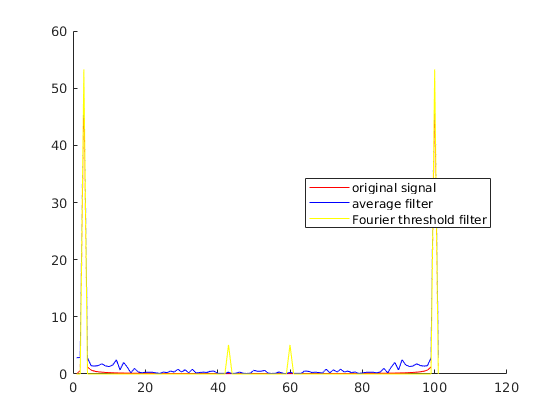

Fy(abs(Fy)<5) = 0.0;
figure(3)
hold on
plot(abs(Ff),'r');plot(abs(fft(f1)),'b');plot(abs(Fy),'y');
legend('original signal','average filter','Fourier threshold filter','Location','best')
hold off

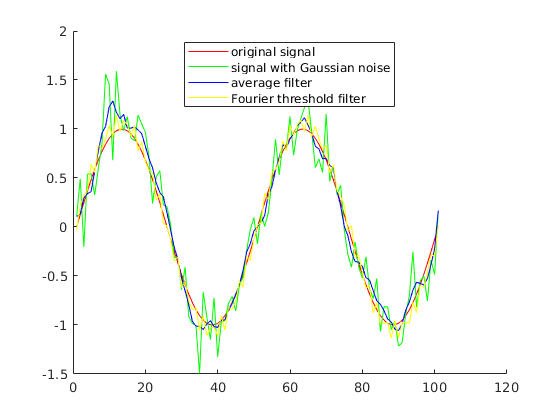

f2 = ifft(Fy);
figure(4)
hold on
plot(f,'r');plot(y,'g');plot(f1,'b');plot(f2,'y')
legend('original signal','signal with Gaussian noise','average filter','Fourier threshold filter','Location','best')
hold off

snr1 = snr(f,f1-f)

snr1 = 16.6124

snr2 = snr(f,f2-f)

snr2 = 18.1533

可见在这个问题中傅里叶阈值法更好，因为加入噪声之后信号仍然保持频域稀疏性。

# Q2

fs = 44100; % Standard sample rate
dt = 1/fs; % Standard sampling time interval
T16 = 1/fs*3199; %To determine the time length of a  1/16 note, suggest as an odd number
t16 = 0:dt:T16;
[temp, k] = size(t16);
t1 = linspace(0,16*T16,16*k);% An array with the same length as a full note
t2 = linspace(0,8*T16,8*k);
t4 = linspace(0,4*T16,4*k);
t4d = linspace(0,6*T16,6*k);%A special array represents a 1/4+1/8 note
t8 = linspace(0,2*T16,2*k);
t32 = linspace(0,T16/2,k/2);
mod1 = sin(pi*t1/t1(end));% Defining a basic amplitude function (So that the sound won't suddenly occur or vanish
mod2 = sin(pi*t2/t2(end));
mod4 = sin(pi*t4/t4(end));
mod4d = sin(pi*t4d/t4d(end));
mod8 = sin(pi*t8/t8(end));
mod16 = sin(pi*t16/t16(end));
mod32 = sin(pi*t32/t32(end));
%mod32 = t32/t32;


f0 = 261.6/(2^(1/4)); % 1 = E^b , which is three half tones higher than C tone
ScaleTable = 2.^((1/12)*(0:25));%Other frequencies

% 1/2 notes
mi_2h = mod2.*cos(2*pi*ScaleTable(17)*f0*t2);
do__2h = mod2.*cos(2*pi*ScaleTable(25)*f0*t2);

% 1/4 notes
do_2f = mod4.*cos(2*pi*ScaleTable(13)*f0*t4);
res_2f = mod4.*cos(2*pi*ScaleTable(16)*f0*t4);
mi_2f = mod4.*cos(2*pi*ScaleTable(17)*f0*t4);
fa_2f = mod4.*cos(2*pi*ScaleTable(18)*f0*t4);
fas_2f = mod4.*cos(2*pi*ScaleTable(19)*f0*t4);
so_2f = mod4.*cos(2*pi*ScaleTable(20)*f0*t4);
la_2f = mod4.*cos(2*pi*ScaleTable(22)*f0*t4);
si_2f = mod4.*cos(2*pi*ScaleTable(24)*f0*t4);
do__2f = mod4.*cos(2*pi*ScaleTable(25)*f0*t4);
blkf = zeros(size(mod4));

% 1/8 notes
sos2e = mod8.*cos(2*pi*ScaleTable(9)*f0*t8);
la2e = mod8.*cos(2*pi*ScaleTable(10)*f0*t8);
si2e = mod8.*cos(2*pi*ScaleTable(12)*f0*t8);
do_2e = mod8.*cos(2*pi*ScaleTable(13)*f0*t8);
re_2e = mod8.*cos(2*pi*ScaleTable(15)*f0*t8);
res_2e = mod8.*cos(2*pi*ScaleTable(16)*f0*t8);
mi_2e = mod8.*cos(2*pi*ScaleTable(17)*f0*t8);
fa_2e = mod8.*cos(2*pi*ScaleTable(18)*f0*t8);
so_2e = mod8.*cos(2*pi*ScaleTable(20)*f0*t8);
sos_2e = mod8.*cos(2*pi*ScaleTable(21)*f0*t8);
la_2e = mod8.*cos(2*pi*ScaleTable(22)*f0*t8);
si_2e = mod8.*cos(2*pi*ScaleTable(24)*f0*t8);
blke = zeros(size(mod8));

% 1/32 notes
so_2t = mod32.*cos(2*pi*ScaleTable(20)*f0*t32);
la_2t = mod32.*cos(2*pi*ScaleTable(22)*f0*t32);

    
s = [si2e la2e sos2e la2e, ...
    do_2f blkf re_2e do_2e si2e do_2e, ...
    mi_2f blkf fa_2e mi_2e res_2e, mi_2e, ...
    si_2e la_2e sos_2e la_2e si_2e la_2e sos_2e la_2e,...
    do__2h la_2f do__2f,...
    so_2t la_2t si_2f la_2f+fas_2f so_2f+mi_2f la_2f+fa_2f,...
    so_2t la_2t si_2f la_2f+fas_2f so_2f+mi_2f la_2f+fa_2f,...
    so_2t la_2t si_2f la_2f+fas_2f so_2f+mi_2f fa_2f+res_2f,...
    mi_2h]; %so_2e la_2e
       

s = s/max(s); %Balance the amplitude never greater than 1
audiowrite('Turkey.flac',s,fs);%Save the music to a file

sound(s,fs);%Play the sound

# Q3

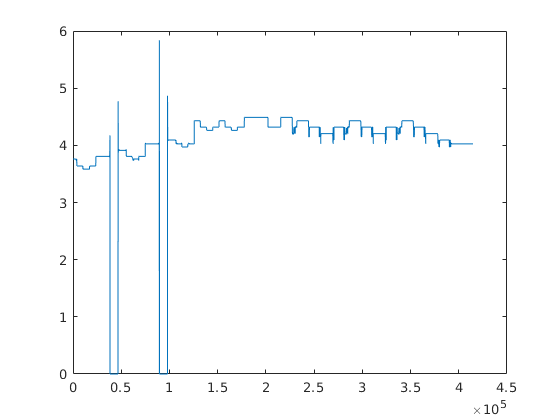

[ys, Fs] = audioread('Turkey.flac');
ub = length(ys)-4410;
height = zeros(ub,1);
for i = 1:ub				
    temp = ys(i:i+4410);
    tempf = fft(temp);
    [maxv, maxp]=max(abs(tempf));
    height(i) = log(maxp);
end	
plot(1:ub,height);

可见音调都基本准确，但是在休止符附近会出现很大的波动。以及，对于后半部分的和声，音符的开始和结束处会有误差。